# AIS data-fusion for ship identification and path tracking

## Read in video files as well as ground truth data

centerVideo = VideoReader('C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\center_camera_VID.mp4');
leftVideo = VideoReader('C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\left_camera_VID.mp4');
rightVideo = VideoReader('C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\right_camera_VID.mp4');

load gTruth_Right.mat;
data = gTruth.LabelData;
bboxes_ship2 = data.ship_2;
bboxes_ship6 = data.ship_6;
bboxes_ship17 = data.ship_17;

Now let's test if the frames are annotated. I'll choose the 400th frame as it includes at least 2 visible classes.

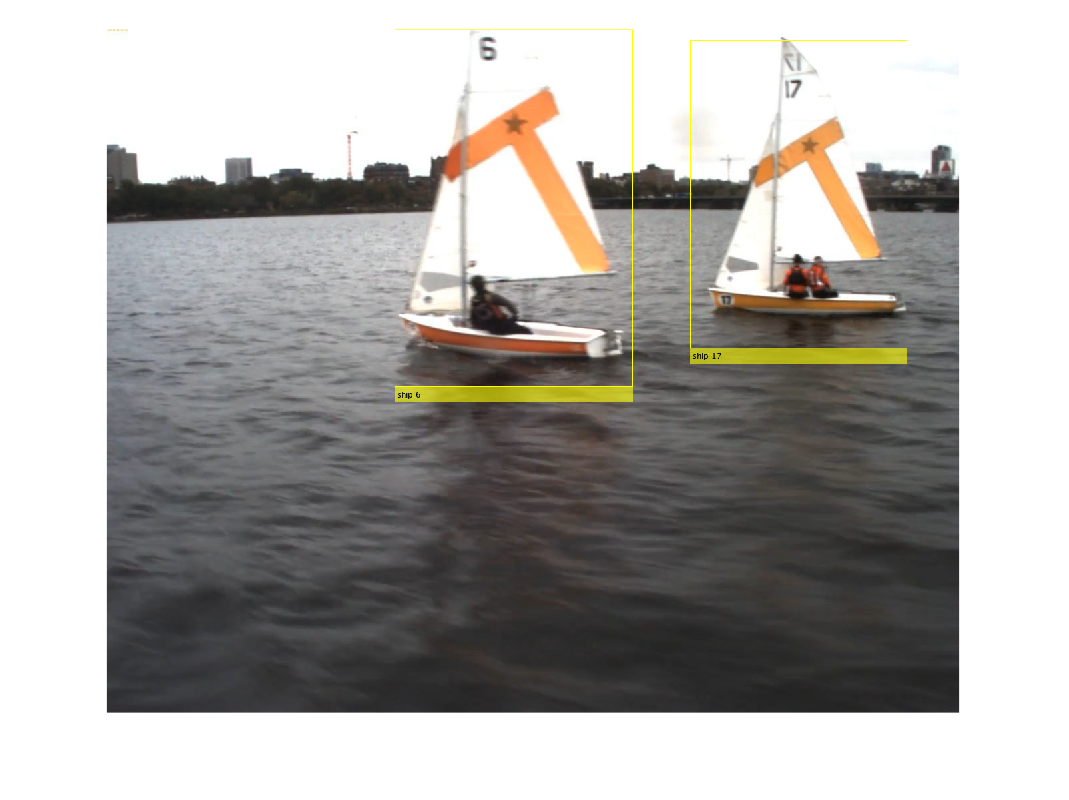

%Need to do a bit more work than before as there are >1 classes now, which
%means there is an error if one of the ships aren't detected in frame:
bboxes400 = [];
labels400 = {};

if ~isempty(bboxes_ship2{400})
    bboxes400 = [bboxes400; bboxes_ship2{400}];
    labels400{end+1} = 'ship 2';
end

if ~isempty(bboxes_ship6{400})
    bboxes400 = [bboxes400; bboxes_ship6{400}];
    labels400{end+1} = 'ship 6';
end

if ~isempty(bboxes_ship17{400})
    bboxes400 = [bboxes400; bboxes_ship17{400}];
    labels400{end+1} = 'ship 17';
end

frame400 = read(rightVideo, 400);
imshow(insertObjectAnnotation(frame400, 'rectangle', bboxes400, labels400))

Alright so it appears to be working. 

## Training data

Create image and bbox datastores from the ground truth data. I will use every 4th frame of gTruth for this.

[imList, boxLabels] = objectDetectorTrainingData(gTruth, WriteLocation = 'Training_Set_Videos');


Write images extracted for training to folder: 
    Training_Set_Videos

Writing 158 images extracted from right_camera_VID.mp4...Completed.


Combine these such that they are acceptable inputs to the yolox network:

gtData = combine(imList,boxLabels);

Now it would be nice to split the dataset into training, validation and testing, and have each of these sets have the same number of labels for each class.

First shuffle the data:

gtShuffled = shuffle(gtData);
numFiles = numpartitions(gtShuffled);


Split it 70% training, 10% validation and 20% test:

numTraining = floor(numFiles*0.7);
numValidation = floor(numFiles*0.1);
gtTrain = subset(gtShuffled,1:numTraining);
gtVal = subset(gtShuffled,(numTraining+1):(numTraining+numValidation));
gtTest = subset(gtShuffled, (numTraining + numValidation + 1):numFiles);


Initialize the detector (YOLOX):

detector = yoloxObjectDetector("tiny-coco", gTruth.LabelDefinitions.Name, InputSize=[640 512 3]);

Create training options:

options = trainingOptions('adam', MiniBatchSize = 2, MaxEpochs = 10, InitialLearnRate = 1e-4, ValidationData = gtVal, ValidationFrequency = 8, ExecutionEnvironment = 'cpu', Verbose = true, Plots = 'training-progress');

Train the detector:

ship_DetectorV1 = trainYOLOXObjectDetector(gtTrain, detector, options)

Let's test it on a frame

frame440 = read(rightVideo, 440);
[dbox, dscore, dlabel] = detect(ship_DetectorV1, frame440);
imshow(insertObjectAnnotation(frame440, 'rectangle', dbox, dlabel));

It appears to work. Let's test on whole video:

rightVideo = VideoReader('C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\right_camera_VID.mp4');
outFile = 'C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\Outputs';

v = VideoWriter(outFile, 'MPEG-4');   % or 'Motion JPEG AVI'
v.FrameRate = rightVideo.FrameRate;
open(v);
frame = readFrame(rightVideo);

while (hasFrame(rightVideo) ~= 0)
     frame = readFrame(rightVideo);
     [bbox,score, label] = detect(ship_DetectorV1,frame);
     img = insertObjectAnnotation(frame,"rectangle",bbox,label);

     writeVideo(v, img);     % ← THIS exports the frame

     imshow(img);
     drawnow
end 
close(v);


Run once, probably already done! Saves the ship detector.

save('C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\ShipDetector','ship_DetectorV1');


## Evaluation of ship_DetectorV1

To evaluate the performance of the first draft of the ship detector, I will calculate the confusion matrix:

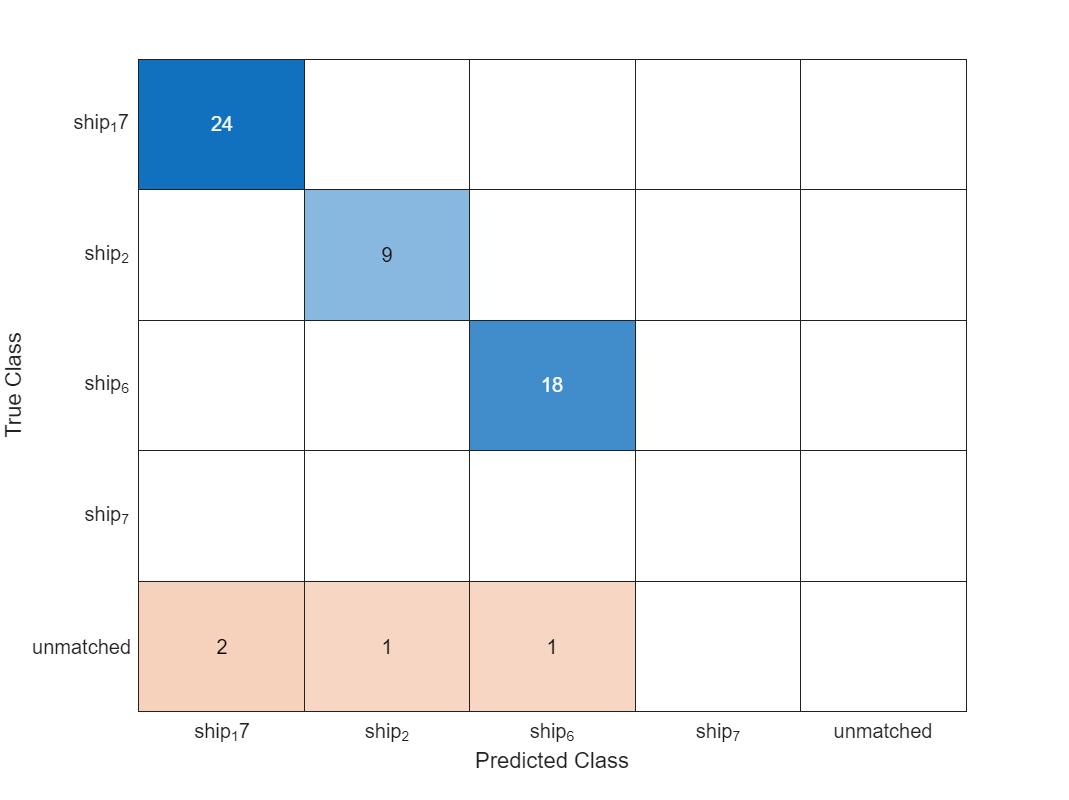

load ShipDetector.mat
results = detect(ship_DetectorV1, gtTest);
metrics = evaluateObjectDetection(results, gtTest);
[confMat, confLabels] = confusionMatrix(metrics);
confusionchart(confMat{1}, confLabels);